1.

A = [1 4 2; 2 4 100; 7 9 7; 3 pi 42];
B = log(A);

(a) B의 두 번째 행을 선택하라.

disp(B(2, :));

    0.6931    1.3863    4.6052



(b) B의 두 번째 행의 합을 구하라.

disp(sum(B(2, :)));

    6.6846



(c) B의 두 번째 열과 A의 첫 번째 열의 원소별 곱을 구하라

B2 = B(:, 2);
A1 = A(:, 1);
R = B2 .* A1;
disp(R);

    1.3863
    2.7726
   15.3806
    3.4342



(d) 위 결과 벡터의 최대값을 구하라.

disp(max(R));

   15.3806



(e) 원소별 나눗셈을 사용하여 A의 첫 번째 행을 B의 세 번째 열의 처음 세 원소로 나누고, 결과 벡터의 합을 구하라.

A11 = A(1, :);
B3 = B(1:3, 3);
R2 = A11 ./ B3.';
disp(sum(R2));

    3.3391



2.

cv = 50;
A = deg2rad(50);
g = 9.81;
x = @(t)cv * cos(A) * t;
y = @(t)cv * sin(A)* t - (g*t.^2)/2;

(a)

t_hit = (2 * cv * sin(A)) / g;
y_max = (cv * sin(A))^2 / (2 * g);
disp(t_hit);

    7.8088



disp(y_max);

   74.7737



(b)

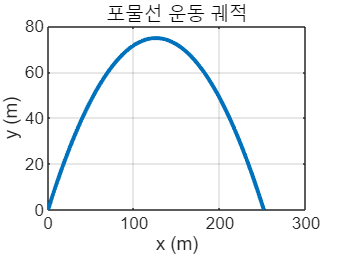

t = linspace(0, t_hit, 200);
figure;
plot(x(t), y(t), 'LineWidth', 2);
grid on;
xlabel('x (m)');
ylabel('y (m)');
title('포물선 운동 궤적');

3.

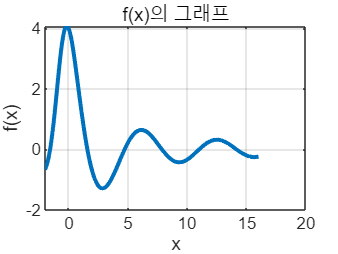

f = @(x) (4*cos(x))./(x+exp(-0.75 * x));
x = linspace(-2, 16, 200);
figure;
plot(x, f(x), 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f(x)');
title('f(x)의 그래프');

4.

c = [5 4 6; 3 2 4; 6 5 3; 3 5 4; 2 4 3];
price = [300;550;400;250;500];
disp(price' *c);

        7300        7550        7700



(c)

disp(price .* sum(c,2));

        4500
        4950
        5600
        3000
        4500



(d)

disp(sum(price' *c));

       22550



5.

fa1 = [5 0 -3 7 10];
fa2 = [0 4 -7 9 2];
disp(conv(fa1, fa2));

     0    20   -35    33    59   -36   -13   104    20



(b)

fb1 = [5 -7 2 8];
fb2 = [6 3 -2];
[q,r] = deconv(fb1, fb2);
disp(q);

    0.8333   -1.5833



disp(r);

         0         0    8.4167    4.8333



(c) 

fc1 = [36 -8 0 2];
fc2 = [36 -5 4 -3];
x = 5;
f1 = polyval(fc1, x);
f2 = polyval(fc2, x);
disp(f1/f2);

    0.9795



7.

위치

bridge(1).space = 'Smith St.';
bridge(2).space = 'Hope Ave.';
bridge(3).space = 'Clark St.';
bridge(4).space = 'North Rd.';

최대하중

bridge(1).max = 80;
bridge(2).max = 90;
bridge(3).max = 85;
bridge(4).max = 100;

건설연도

bridge(1).year = 1928;
bridge(2).year = 1950;
bridge(3).year = 1933;
bridge(4).year = 1960;

유지기한(년)

bridge(1).exp = 2025;
bridge(2).exp = 2027;
bridge(3).exp = 2024;
bridge(4).exp = 2023;
T = struct2table(bridge);
disp(T);

        space        max    year    exp 
    _____________    ___    ____    ____

    {'Smith St.'}     80    1928    2025
    {'Hope Ave.'}     90    1950    2027
    {'Clark St.'}     85    1933    2024
    {'North Rd.'}    100    1960    2023
    {'Shore Rd.'}     85    1997    2022



(b)

bridge(3).exp = 2026;
disp(bridge(3));

    space: 'Clark St.'
      max: 85
     year: 1933
      exp: 2026



(c)

bridge(5).space = 'Shore Rd.';
bridge(5).max = 85;
bridge(5).year = 1997;
bridge(5).exp = 2022;
T = struct2table(bridge);
disp(T);

        space        max    year    exp 
    _____________    ___    ____    ____

    {'Smith St.'}     80    1928    2025
    {'Hope Ave.'}     90    1950    2027
    {'Clark St.'}     85    1933    2026
    {'North Rd.'}    100    1960    2023
    {'Shore Rd.'}     85    1997    2022

